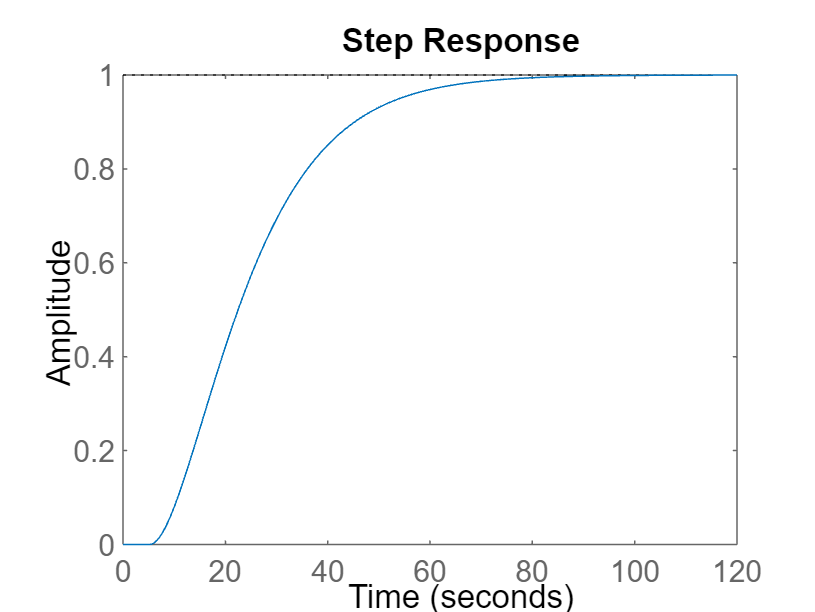

%CISLICOVE RIADENIE      -
%ZADANIE 1 SAMUEL HACKER -
%------------------------------------------
% Transfer function
%   1/(10.3s+1)^2
citatel = 1;
menovatel = [106.09 20.6 1];                   
G = tf(citatel,menovatel,'InputDelay',5.2) ; %dve moznosti
%G = tf(1,[106.09 20.6 1],'InputDelay',5.2) ;
step(G)

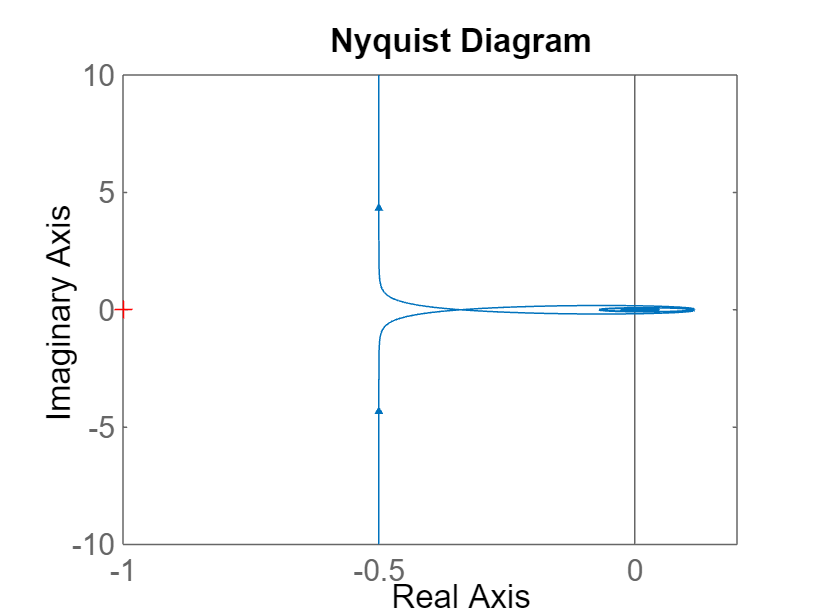


t1= 10.3; % T zo zadanej funkcie      
t2= 10.3; % dvojnasobne T
d= 5.2;   % transport delay

%------------------------------------------
%metoda optimalneho modulu
% p1= T1 + T2 + D
% pk= T1^k + T2^k;

p1= t1+t2+d;
p2= t1^2 + t2^2;
p3= t1^3 + t2^3;
p4= t1^4 + t2^4;
p5= t1^5 + t2^5;

%a str83
a0=1;
a1=p1;
a2=(p1^2-p2)/2;
a3=(p1^3-3*p1*p2+2*p3)/6;
a4=(p1^4-6*p1^2*p2+8*p1*p3+3*p2^2-6*p4)/24;
a5=(p1^5-10*p1^3*p2+20*p1^2*p3+15*p1*p2^2-30*p1*p4-20*p2*p3+24*p5)/120;

K=1;        %zosilnenie K
F=1/(2*K);

%matica 
A = [a1 -1 0; a3 -a2 a1; a5 -a4 a3];
b = [F*1; F*(-a1^2 + 2*a2); F*(a2^2 - 2*a1*a3 + 2*a4)];

x= A\b;

%zadefinovane hodnoty PID pre simulink 
I=x(1);
P=x(2);
D=x(3);
%------------------------------------------
%STABILITA
%sys je stabilny ak korene lezia v lavej polrovine 
Gd=pade(G,1);%padeho rozvoj po 1. clena  cize 0. a 1. clen nek radu cit a men
Gr = tf([x(3) x(2) x(1)],[1 0] ); %Gr = tf([D P I],[1 0] );
nyquist(G*Gr); %frekv char otv reg obv, stabilita -> kryticky bod je -1 a 0

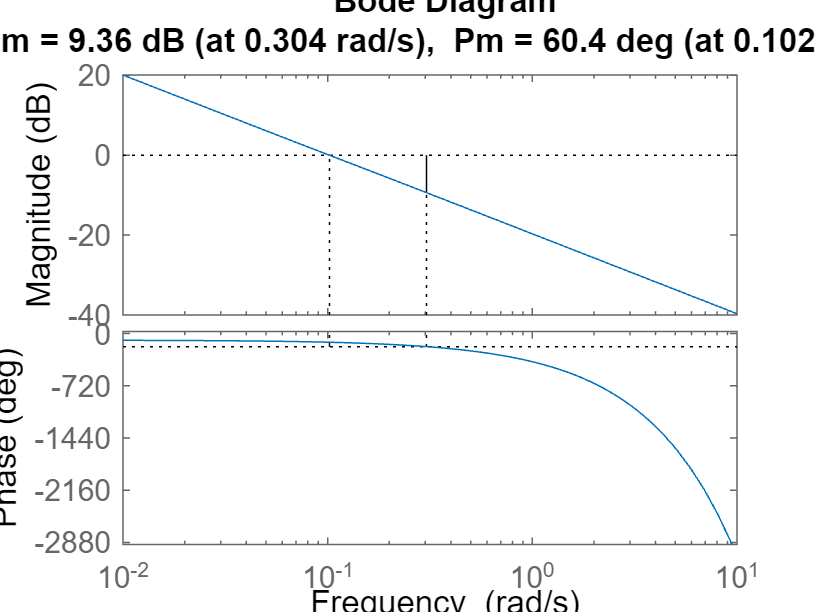

figure;
margin(G*Gr);


CHRURO=minreal(Gd*Gr/(1+Gd*Gr)) 

CHRURO =
 
                                                      
  -0.1038 s^5 - 3.028e-05 s^4 + 0.009596 s^3          
                                                      
               + 0.00185 s^2 + 0.0001338 s + 3.445e-06
                                                      
  ----------------------------------------------------
                                                      
  s^6 + 0.6691 s^5 + 0.2059 s^4 + 0.03501 s^3         
                                                      
               + 0.003346 s^2 + 0.000168 s + 3.445e-06
                                                      
 
Continuous-time transfer function.



polyURO=CHRURO.Denominator{1}

polyURO =     1.0000    0.6691    0.2059    0.0350    0.0033    0.0002    0.0000



roots(polyURO) %zisti tie korene , resp poly uzavr reg bodu

ans =   -0.1445 + 0.1444i
  -0.1445 - 0.1444i
  -0.0930 + 0.0107i
  -0.0930 - 0.0107i
  -0.0971 + 0.0000i
  -0.0971 - 0.0000i


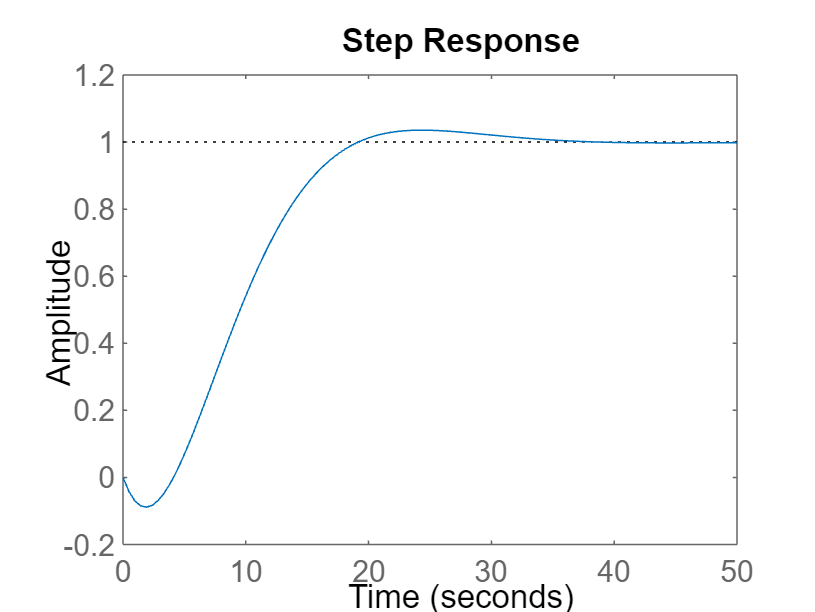

step(CHRURO);%menej presny graf ako v simulinku

stepinfo(CHRURO)

ans = struct with fields:
         RiseTime: 10.2102
    TransientTime: 29.7803
     SettlingTime: 30.2837
      SettlingMin: 0.9039
      SettlingMax: 1.0355
        Overshoot: 3.5547
       Undershoot: 8.8756
             Peak: 1.0355
         PeakTime: 24.1910


%------------------------------------------
%Inverzia dynamiky
beta= 1.944;
a=1/(beta*d);

Ti=t1+t2;
Pp=(a/K)*Ti; %P
Td=(t1*t2)/(t1+t2);
%Gr=(Pp*(1+(1/Ti)+Td));

%I
I2=Pp/Ti;

%D
D2=Pp*Td;

%------------------------------------------
%Metóda sumy časových konštánt
Ts= t1+t2+d; %v podstate a1
Psck=2/K;
TIsck=0.8*Ts;
I3=Psck/TIsck;
TDsck=0.194*Ts;
D3=Psck*TDsck;

%------------------------------------------
%limity prenosovej funkcie
syms s 
%hodnoty do lim_GR mam y variable Gr
%lim_GR = (D + P + I/s);
lim_GR=(11.014081150611170 + 2.100740931965868 *s + 0.100803912091700*s^2)/s;%GR

lim_GS=(1/(106.09*s*s + 20.6*s+1)) ;%GS
%G = tf(K je 1/(106.09*s*s prvy clen*s2 + 20.6*s druhy clen*s1 +1)) ;
%e=(1/(1+G*Gr));
e = 1 / ( 1 + lim_GR*lim_GS);
Lim_e=limit(e, s, 0)

$$Lim\_e = 0$$


%Y=G(s)*G(r)/1+G(s)*G(r)
%lim s->1
y=lim_GS*lim_GR/(1+lim_GS*lim_GR);
Lim_y=limit(y, s, 0)

$$Lim\_y = 1$$


%lim s->1
u=((lim_GR)/(1+(lim_GR*lim_GS)));
Lim_u=limit(u, s, 0)

$$Lim\_u = 1$$

%plot(out.ScopeData1)
